clear;
% 第一遍数据
delta = 5; 
desire_score=0.85;
read_file='data\all_results.mat';
save_file='data\extra_data_1.mat';
% %第二遍数据
% delta = 2.5;
% desire_score=0.85;
% read_file='data\extra_data_1.mat';
% save_file='data\extra_data_2.mat';
% %第三遍数据
% delta = 1.25;
% desire_score=0.87;
% read_file='data\extra_data_2.mat';
% save_file='data\extra_data_3.mat';
r=load(read_file);
rough_combinations=r.good_combinations;
for i = 1:6
    L_max(i)=max(rough_combinations(:,i));
    L_min(i)=min(rough_combinations(:,i));
end

L_max = 200

L_min = 110

L_max =    200   250


L_min =    110   130


L_max =    200   250   250


L_min =    110   130   210


L_max =    200   250   250   110


L_min =    110   130   210    80


L_max =    200   250   250   110   175


L_min =    110   130   210    80   145


L_max =    200   250   250   110   175   150


L_min =    110   130   210    80   145   100


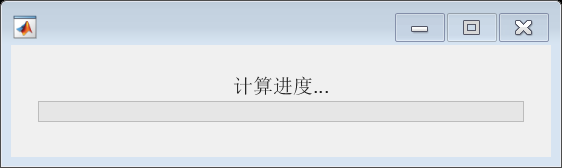

D = parallel.pool.DataQueue;
h = waitbar(0, '计算进度...');

h.UserData = 0; % 初始化计数器
batchSize=1000;
% 初始化GPU
if gpuDeviceCount > 0
    disp('GPU is available');
    useGPU = true;
else
    error('No GPU available');
end

GPU is available


%% 定义邻近组合生成参数
deadline = 0.8;  % 沿用原误差阈值
%% 生成邻近组合
% 定义参数范围和变化步长
param_ranges = [max(50,L_min(1))  min(250,L_max(1));    % L1
                max(50,L_min(2))  min(250,L_max(2));    % L2
                max(50,L_min(3))  min(250,L_max(3));    % L3
                max(50,L_min(4))  min(250,L_max(4));    % L4
                max(145,L_min(5))  min(175,L_max(5));    % L5
                max(100,L_min(6))  min(160,L_max(6))];   % L6

% 预计算有效参数索引
valid_params = cell(6,1);
for i = 1:6
    valid_params{i} = param_ranges(i,1):delta:param_ranges(i,2);
end

% 初始化新组合矩阵
new_combinations = zeros(0,6);

% 逐行处理原始组合
for i = 1:size(rough_combinations,1)
    original = rough_combinations(i,:);
    
    % 对每个参数生成邻近值
    neighbors = cell(6,1);
    for p = 1:6
        current_val = original(p);
        candidates = [current_val - delta, current_val, current_val + delta];
        % 筛选有效值并去重
        valid = unique(candidates(...
            candidates >= param_ranges(p,1) & ...
            candidates <= param_ranges(p,2)));
        % 转换为离散参数空间
        [~, idx] = min(abs(valid_params{p} - valid'), [], 2);
        neighbors{p} = unique(valid_params{p}(idx));
    end
    
    % 生成邻近组合（单参数变化模式）
    for p = 1:6
        for val = neighbors{p}
            if val == original(p), continue; end % 跳过原始值
            new_row = original;
            new_row(p) = val;
            new_combinations = [new_combinations; new_row];
        end
    end
end

% 合并并去重（使用容差去重）
tol = 1e-6;
all_combinations = [rough_combinations; new_combinations];
[~,idx] = unique(round(all_combinations/tol),'rows','stable');
new_combinations = all_combinations(sort(idx),:);

sector = struct(...
    'r_min', 100,...   % 内半径
    'r_max', 350,...  % 外半径
    'theta_min', deg2rad(-140),...  % 起始角度（弧度）
    'theta_max', deg2rad(-40)...  % 终止角度（弧度）
);

% 预处理：预先计算角度边界的三角函数值以加速计算
sector.sin_theta_min = sin(sector.theta_min);
sector.cos_theta_min = cos(sector.theta_min);
sector.sin_theta_max = sin(sector.theta_max);
sector.cos_theta_max = cos(sector.theta_max);
% 计算扇区面积
sector_area = (sector.r_max^2 - sector.r_min^2)*(sector.theta_max-sector.theta_min)/2;
% %样例测试，小范围
% [F_x, F_y] = calculateTrajectory(150, 170, 270, 100, 170,100, 0,sector);
% figure;
% scatter(F_x, F_y, 5, 'filled');
% hold on;
% 
% % Plot the circles
% 
% for r = 100:50:350
%     theta = linspace(sector.theta_min, sector.theta_max, 1000); % 足够多的点使曲线平滑
%     x = r * cos(theta);
%     y = r * sin(theta);
%     plot(x, y, 'Color', [0.5 0.5 0.5], 'LineStyle', '--'); % 灰色虚线
% end
% 
% % Add the transparent fan ring
% theta_fan = linspace(sector.theta_min,sector.theta_max, 100); % Angular range from 1.25pi to 1.75pi
% r_inner = 100; % Inner radius
% r_outer = 350; % Outer radius
% 
% % Coordinates for the inner and outer edges of the fan ring
% x_inner = r_inner * cos(theta_fan);
% y_inner = r_inner * sin(theta_fan);
% x_outer = r_outer * cos(theta_fan);
% y_outer = r_outer * sin(theta_fan);
% 
% % Create the filled sector (fan ring) by connecting the inner and outer edges
% fill([0, x_outer, fliplr(x_inner)], [0, y_outer, fliplr(y_inner)], 'y', 'FaceAlpha', 0.4, 'EdgeColor', 'none'); 
% hold off;
% xlabel('X (mm)');
% ylabel('Y (mm)');
% title('五连杆末端点云轨迹');
% xlim([-200, 200]);
% 
% ylim([-350, -100]);
% axis equal;
% grid on;
% scores(1)=evaluateSectorOptimized(F_x,F_y,0,sector_area);

% 设置监听器
total_combinations=length(new_combinations);
afterEach(D, @(~) updateWaitbar(h, total_combinations));
% 主计算循环
is_valid=true(1,total_combinations);
scores=single(zeros(total_combinations,1));
parfor i = 1:total_combinations  % 使用parfor并行计算
    % 获取当前参数组合
    current_params = new_combinations(i, :);
    [L1, L2, L3, L4, L5,L6] = deal(current_params(1), current_params(2),...
                               current_params(3), current_params(4),...
                               current_params(5),current_params(6));
    try
        [F_x, F_y] = calculateTrajectory(L1, L2, L3, L4, L5,L6, useGPU,sector);
        scores(i)=evaluateSectorOptimized(F_x,F_y,0,sector_area)
    catch ME
        is_valid(i)=false;
        warning('函数计算出错');
    end
    if mod(i, batchSize) == 0
        send(D, batchSize); % 发送批量大小作为增量
    end
end


close(h); % 关闭进度条
delete(h);
% 保存完整结果
good_combinations=new_combinations;
good_combinations(:,7)=scores(:);
good_combinations=good_combinations(is_valid,:);
valid_score=scores>desire_score;
good_combinations=good_combinations(valid_score,:);
[~, sort_idx] = sort(good_combinations(:, end), 'descend');
top100_params=good_combinations(sort_idx(1:100),:);
save(save_file,'good_combinations','sort_idx','top100_params');
clear;
toc;

历时 4129.802803 秒。
